# HW 2 - Matlab Exercise 2

Module 2 consists of 8 sections. loading data as we did before is where we begin

data = load('../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt');
% loading in the data from the csv matrix
converted_data = convert(data);
x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

## Combining of signal

can be done with an anon function

S = @(a, b, c) (sqrt(a.^2 + b.^2 + c.^2 ))

with this we can convert the signal for computing the energy of it.


$$E=\int_{-\infty }^{\infty } |S|^2 \mathrm{dt}$$


We are in a discrete environment, so we need the following.


$$E=\sum_{-\infty }^{\infty } |S|^2$$


matlabs sum function can do this across the vector and we can pass in the squared magnitude

E = sum(mag_sigquared)

## 2 combine and calculate energy

sig_sig = S(x, y, z)';
mag_sigquared = abs(sig_sig).^2;
energy_sig = sum(mag_sigquared,"all","omitmissing","double")

The energy of S is obtained.

## 3 Implementation of moving average

showing the moving average working on the data below. this does not have names on the plots, but we can make a names vector for it and add it programatically

plot_avgs(x)
plot_avgs(y)
plot_avgs(z)

## get all at once with the data and converted data

for i = 1:3
    figure
    plot_avgs(data(:,i))
    pause(.1)
    figure
    plot_avgs(converted_data(:,i))
    pause(.1)
end

## Here is the convolved impulse $\delta$ across the signals 

impulse = 1;
conv_sig = conv(x,impulse);
hx = filter(impulse,1,x);
hy = filter(impulse,1,y);
hz = filter(impulse,1,z);
reg_range = (1:1:length(hx))';
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with impulse and filter function')
legend("h_x","x","\delta")
grid on

## 4 Recursive system 1

These are the plots of the recursive system for problem 4 

figure()
diff1_x = [diffeq_1(x),x];
plot(diff1_x)
title('Original signal with diff eq function 1')
legend("y(n)","x(n)")
grid on

figure()
diff1_y = [diffeq_1(y),y];
plot(diff1_y)
title('Original signal with diff eq function 1')
legend("y'(n)","y(n)")
grid on

figure()
diff1_z = [diffeq_1(z),z];
plot(diff1_z)
title('Original signal with diff eq function 1')
legend("y(n)","z(n)")
grid on


## 5 Recursive system 2

figure()
diff2_x = [diffeq_2(x),x];
plot(diff2_x)
title('Original signal with diff eq function 2')
legend("y(n)","x(n)")
grid on

figure()
diff2_y = [diffeq_2(y),y];
plot(diff2_y)
title('Original signal with diff eq function 2')
legend("y'(n)","y(n)")
grid on

figure()
diff2_z = [diffeq_2(z),z];
plot(diff2_z)
title('Original signal with diff eq function 2')
legend("y(n)","z(n)")
grid on

This system is computing a cumulative average. I cannot remember the term mentioned in class, but we can see that the last value calculated is one thatcounts toward the sum the least overall. same effect as having an average that you add one more value to, it is by definition a single value more than the average had increased by prior to this addition. the y term being multiplied by n shows that it must be first multiplied by the total number of elements that had been included thusfar.

## 6 Recursive system 3

x = data(:,1);
y = data(:,2);
z = data(:,3);
figure()
diff3_x = [diffeq_3(x),x];
plot(diff3_x)
title('Original signal with diff eq function 3')
legend("y(n)","x(n)")
grid on

figure()
diff3_y = [diffeq_3(y),y];
plot(diff3_y)
title('Original signal with diff eq function 3')
legend("y'(n)","y(n)")
grid on

figure()
diff3_z = [diffeq_3(z),z];
plot(diff3_z)
title('Original signal with diff eq function 3')
legend("y(n)","z(n)")
grid on

## recursive shift for system 1 on x data and converted x data to see differences and test LTI

x = data(:,1);
y = data(:,2);
z = data(:,3);
figure
lti_test1(x,1,'original x ')
figure
lti_test1(y,1,'original y ')
figure
lti_test1(z,1,'original z ')

x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

figure
lti_test1(x,1,'converted x ')
figure
lti_test1(y,1,'converted y ')
figure
lti_test1(z,1,'converted z ')

## recursive shift for system 2 on x data and converted x data to see differences and test LTI

x = data(:,1);
y = data(:,2);
z = data(:,3);
figure
lti_test2(x,1,'original x ')
figure
lti_test2(y,1,'original y ')
figure
lti_test2(z,1,'original z ')

x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

figure
lti_test2(x,1,'converted x ')
figure
lti_test2(y,1,'converted y ')
figure
lti_test2(z,1,'converted z ')

## recursive shift for system 3 on x data and converted x data to see differences and test LTI

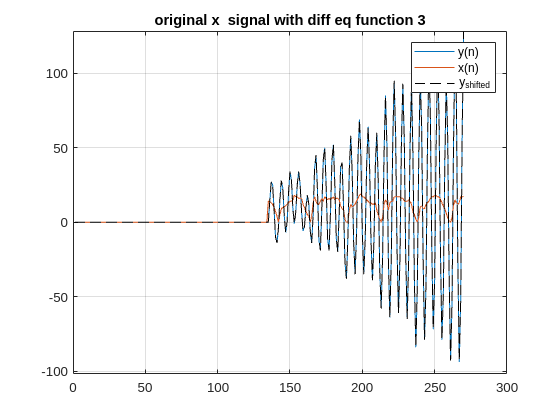

x = data(:,1);
y = data(:,2);
z = data(:,3);
figure
lti_test3(x,1,'original x ')

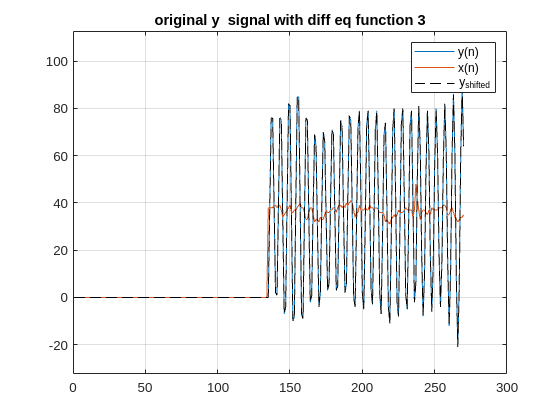

figure
lti_test3(y,1,'original y ')

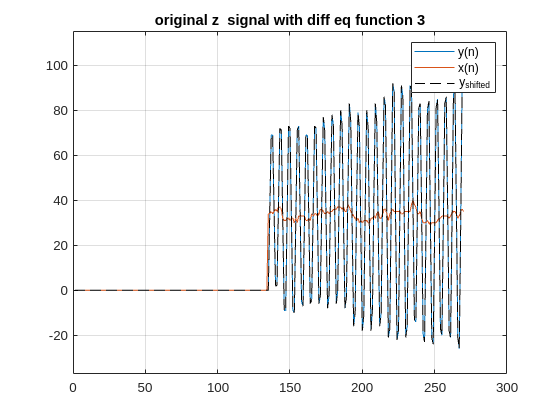

figure
lti_test3(z,1,'original z ')

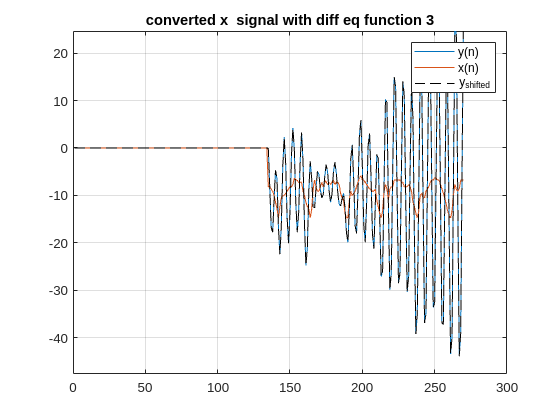


x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

figure
lti_test3(x,1,'converted x ')

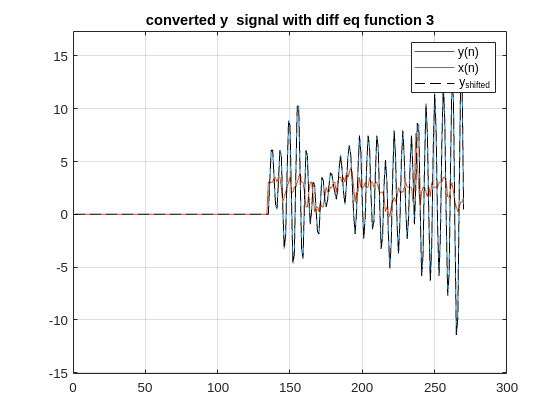

figure
lti_test3(y,1,'converted y ')

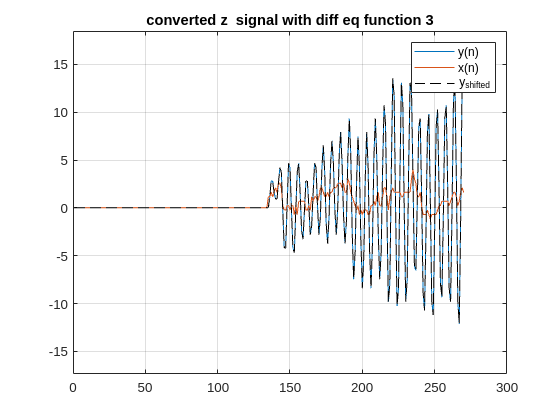

figure
lti_test3(z,1,'converted z ')

## Problem 2.65 from text parts a-d

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end

function plot_avgs(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
plot(1:1:length(x),x,'b',2:1:(length(conv_sig)-1),conv_sig(2:end-1),'r');
title('combined signal and moving avg')
xlabel('samples n')
ylabel('value')
grid on
legend('original','avg')
end

% not actually the cross corr function since this isnt time rev. more like
% an auto corr
function crossCorr(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
hx = filter(avg_vec,1,x);
convX = conv(hx,x);
reg_range = (1:1:length(hx))';
new_range = -floor(length(convX)/2):1:floor(length(convX)/2);
figure()
plot(new_range,convX)
grid on
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with average and filter function')
legend("h_x","x","My_{avg}")
grid on
end

% not actually the cross corr function since this isnt time rev. more like
% an auto corr
function cross_corr(x,y,signals)
figure()
plot(x,'k*-')
hold on
plot(y,'b:')
legend("x_{i}(n)","x_{j}(n)")
title("signals x_{i}(n) and x_{j}(n)")
grid on
hold off

figure()
plot(conv(x,flip(y)),'r')
if x == y
hold on
plot(conv(x,y),'b')
title(sprintf("Correlation R_{%s} with autocorr",signals))
legend(sprintf("R_{%s}",signals), "autocorr")
grid on
hold off
else 
title(sprintf("Correlation R_{%s}",signals))
legend(sprintf("R_{%s}",signals))
grid on
end
end

% difference eqs
function y = diffeq_1(x)
    y = zeros(size(x));
    y(1) = 0;
    for n = 2:length(x)
        y(n) = .8*(y(n-1)) + x(n);
    end
end

function y = diffeq_2(x)
    y = zeros(size(x));
    y(1) = 0;
    for n = 2:length(x)
        y(n) = (n/(n+1))*y(n-1) + (1/(n+1))*x(n);
    end
end

function y = diffeq_3(x)
    y = zeros(size(x));
    y(1) = 0;
    y(2) = y(1) + x(2);
    for n = 3:length(x)
        y(n) = y(n-1) - y(n-2) + x(n);
    end
end


function lti_test1(x,t,sig)
for i = 1:1:floor(length(x)/2)
    diff1= [diffeq1(x,t),x];
    plot(diff1)
    ylim([min(min(diff1(:,1)),min(diff1(:,2))) ...
        max(max(diff1(:,1)),max(diff1(:,2))) ]*1.2)
    title(sprintf('%s signal with diff eq function 1',sig))
    grid on
    hold on
    diff1= [diffeq1(x,i),x];
    plot(diff1(:,1),'--k')
    legend("y(n)","x(n)","y_{shifted}")
    hold off
    pause(.05)
end
end


function lti_test2(x,t,sig)
for i = 1:1:floor(length(x)/2)
    x_new = zeros(size(x));
    x_new(i:end) = x(i:end);
    diff2= [diffeq2(x_new,i),x_new];
    plot(diff2)
    ylim([min(min(diff2(:,1)),min(diff2(:,2))) ...
        max(max(diff2(:,1)),max(diff2(:,2))) ]*1.2)
    title(sprintf('%s signal with diff eq function 2',sig))
    grid on
    hold on
    diff2= [diffeq2(x_new,i),x_new];
    neweq = diff2(:,1);
    plot((1:10:length(neweq)),neweq(1:10:end),'--k')
    legend("y(n)","x(n)","y_{shifted}")
    hold off
    pause(.05)
end
end


function lti_test3(x,t,sig)
    diff32 = [diffeq3(x,1),x];
    x_new = zeros(size(x));
for i = 1:1:floor(length(x)/2)
    x_new(i:end) = x(i:end);
    diff3 = [diffeq3(x_new,i),x_new];
    plot(diff3)
    ylim([min(min(diff32(:,1)),min(diff32(:,2))) ...
        max(max(diff32(:,1)),max(diff32(:,2))) ]*1.2)
    title(sprintf('%s signal with diff eq function 3',sig))
    grid on
    hold on
    diff3= [diffeq3(x,i),x];
    neweq = diff3(:,1);
    plot(neweq,'--k')
    legend("y(n)","x(n)","y_{shifted}")
    hold off
    pause(.05)
    x_new(1:end) = 0;
end
end

